clear all;
close all;
clc;

% User Input
wp = input('Enter the Passband Edge Frequency (in Hz): ');
ws = input('Enter the Stopband Edge Frequency (in Hz): ');
deltap = input('Enter the Passband Ripple (\delta_p): ');
deltas = input('Enter the Stopband Ripple (\delta_s): ');
fs = input('Enter the Sampling Frequency (in Hz): ');

% Bilinear Transformation
omegap = 2 * tan(wp*pi/fs) / sqrt(1 + tan(wp*pi/fs)^2);
omegas = 2 * tan(ws*pi/fs) / sqrt(1 + tan(ws*pi/fs)^2);

% Calculate Filter Order
delta = min(1/deltas^2 - 1, 1/deltap^2 - 1);
epsi = 1/deltap^2 - 1;
num = log10(delta/epsi);
den = 2 * log10(omegas/omegap);
N = ceil(num / den);

disp(['Calculated Filter Order (N): ', num2str(N)]);

Calculated Filter Order (N): 1


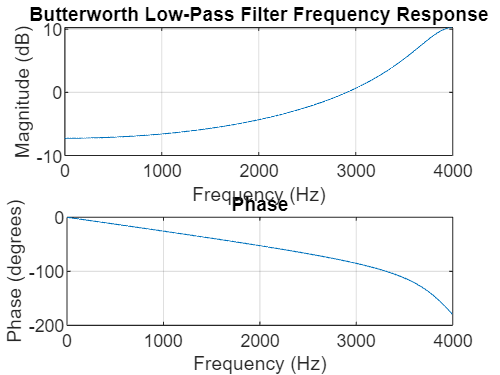


% Design Butterworth Low-Pass Filter
[bb, ab] = butter(N, omegap, 's');

% Plot Frequency Response
figure;
freqz(bb, ab, 1000, fs);
title('Butterworth Low-Pass Filter Frequency Response');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
grid on;